Redoing mtb model on these datasets:

- mtb_h37rv_chandrasekaran_2016.xlsx

- mtb_yilancioglu_2019_mtb.xlsx

indigoData = readtable('all_data.xlsx');
dataFiles = indigoData.Filename(~indigoData.EcoliModelExclusive);

valMethod = 'cv';
K = 5;
standardize = '';
modelType = 2;
input_type = 2;

%testdata = mtb_h37rv_chandrasekaran_2016.xlsx
testData = dataFiles{4};
trainingData = dataFiles([1:4-1 4+1:end]);
indigoSummary = indigoRun(testData,trainingData,valMethod,K,standardize,modelType,input_type);

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training

Results for mtb_h37rv_chandrasekaran_2016

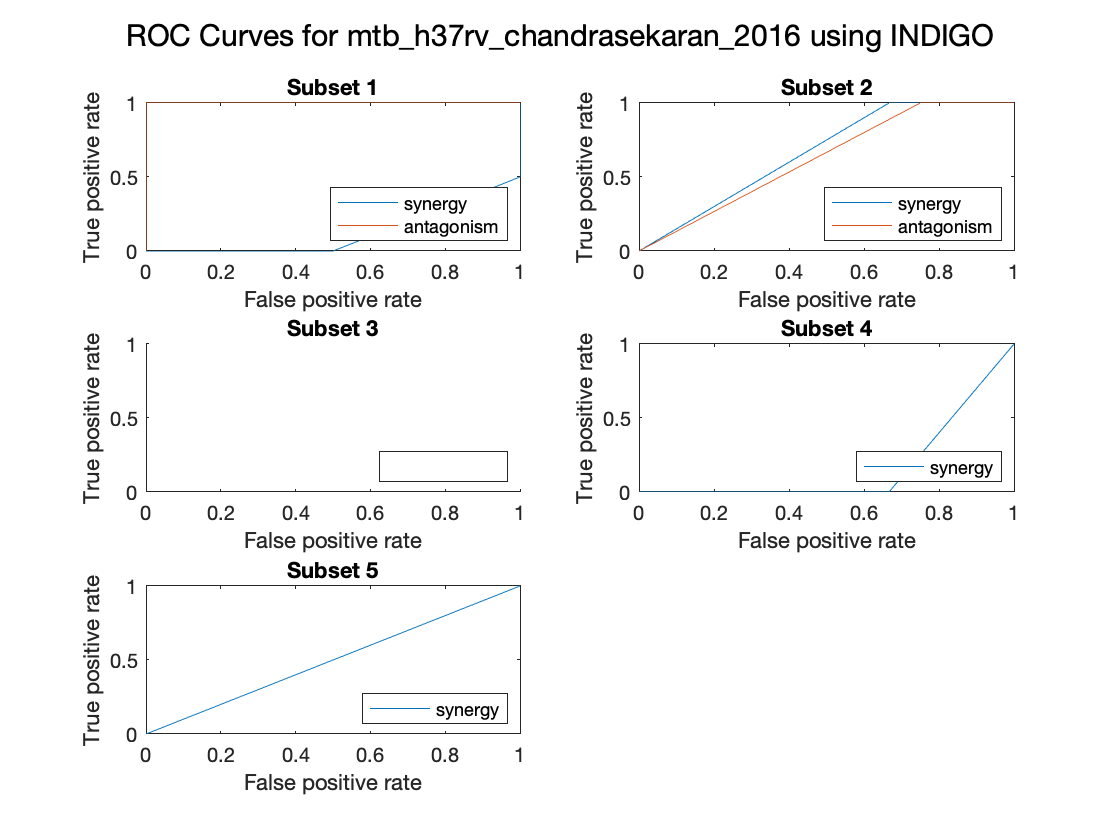

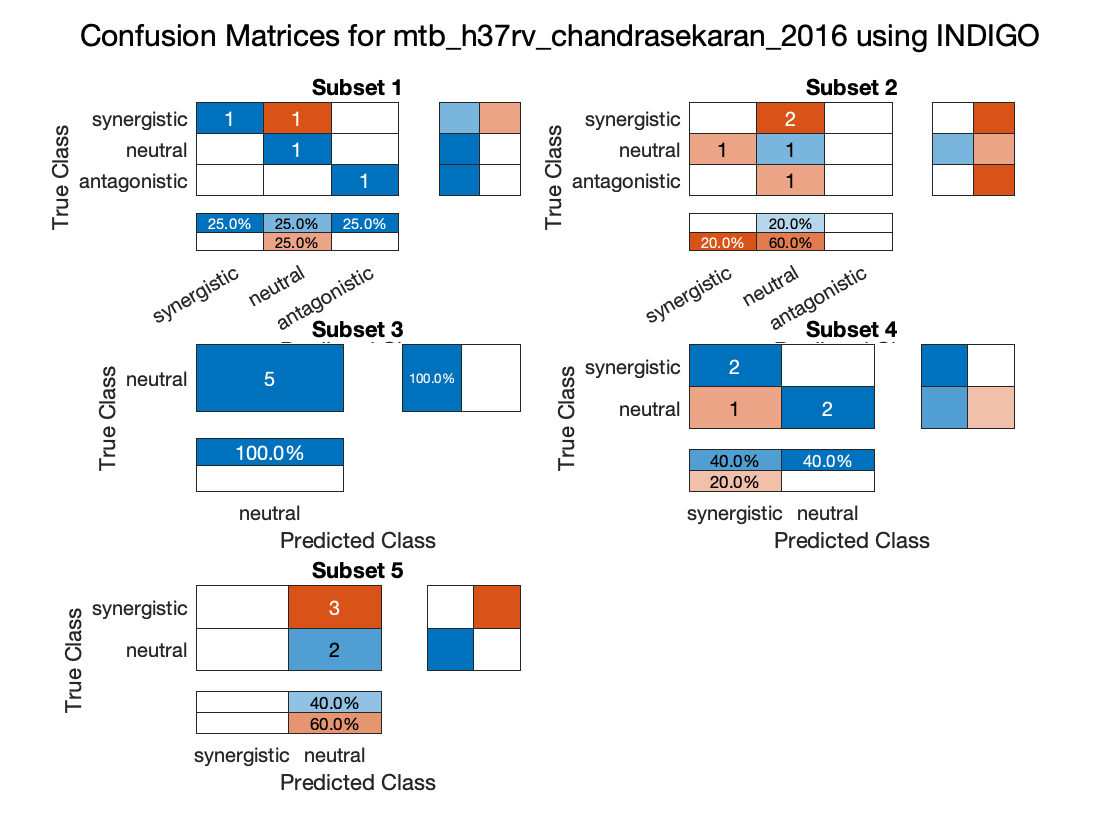

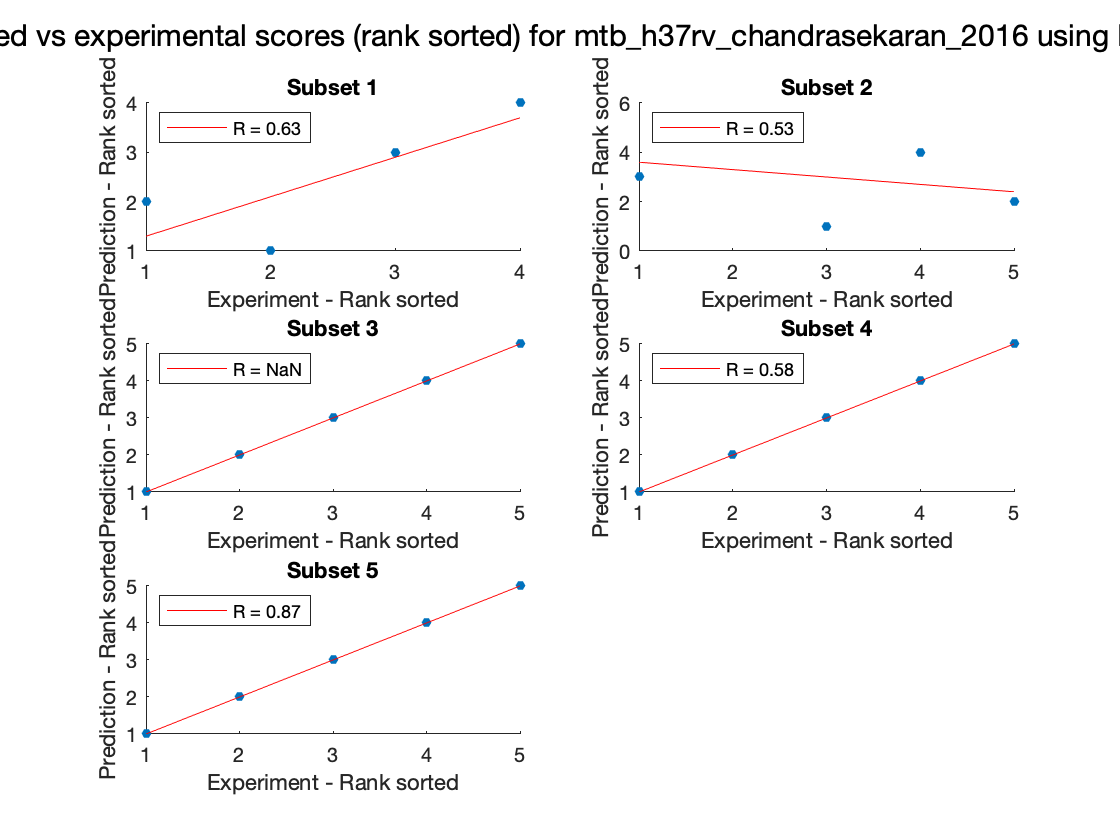

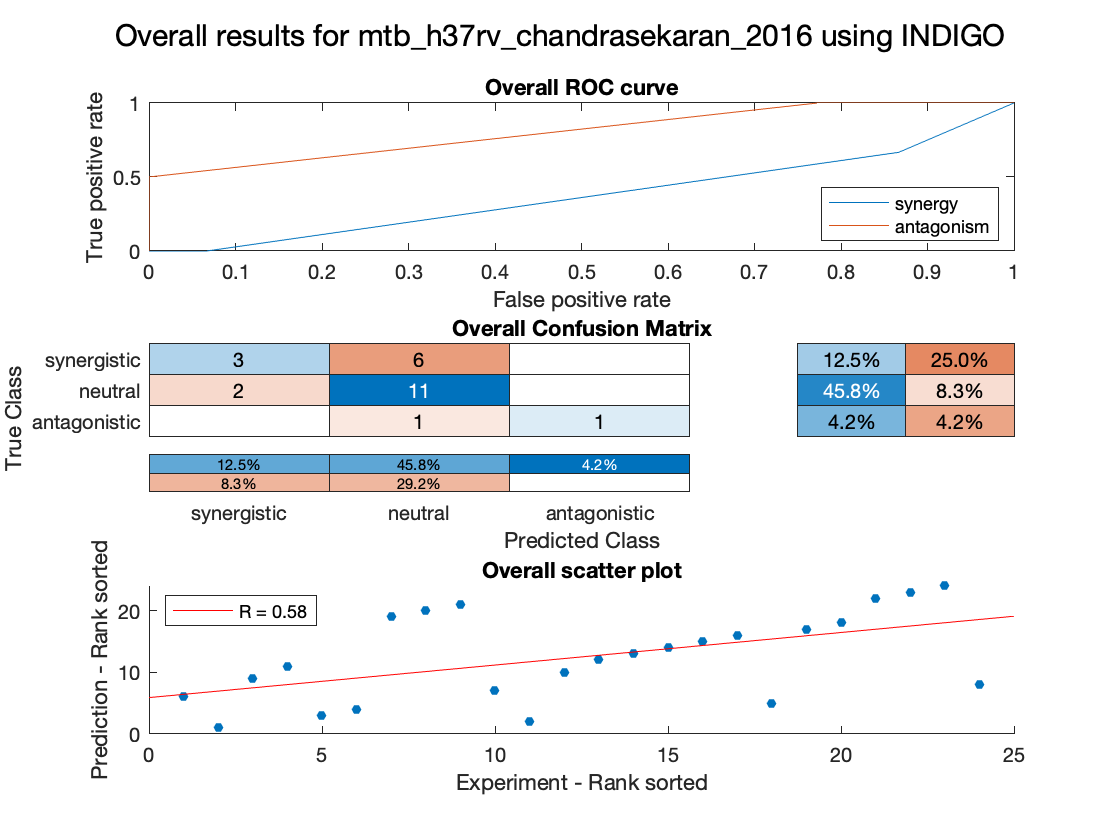

resultsTable = 5×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         4          0.63246         0.5      0.75           0.25                     1                0.5                   

averagesTable = 11×1 table
                              Value
                              _____

    Interactions               4.8 
    R (rank)                   NaN 
    P value                    NaN 
    Accuracy                  0.63 
    Absolute error            0.37 
    Precision (synergy)        NaN 
    Recall (synergy)           NaN 
    Precision (antagonism)     NaN 
    Recall (antagonism)        NaN 
    AUC - ROC (synergy)        NaN 
    AUC - ROC (antagonism)     NaN 


overviewTable = 11×1 table
                                Value  
                              _________

    Interactions                     24
    R (rank)                    0.57558
    P value                   0.0032513
    Accuracy                      0.625
    Absolute error                0.375
    Precision (synergy)             0.6
    Recall (synergy)            0.33333
    Precision (antagonism)            1
    Recall (antagonism)             0.5
    AUC - ROC (synergy)         0.37778
    AUC - ROC (antagonism)      0.80682


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

%testdata = mtb_yilancioglu_2019_mtb.xlsx
testData = dataFiles{18};
trainingData = dataFiles([1:18-1 18+1:end]);
indigoSummary = indigoRun(testData,trainingData,valMethod,K,standardize,modelType,input_type);

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to trai

Results for mtb_yilancioglu_2019_mtb

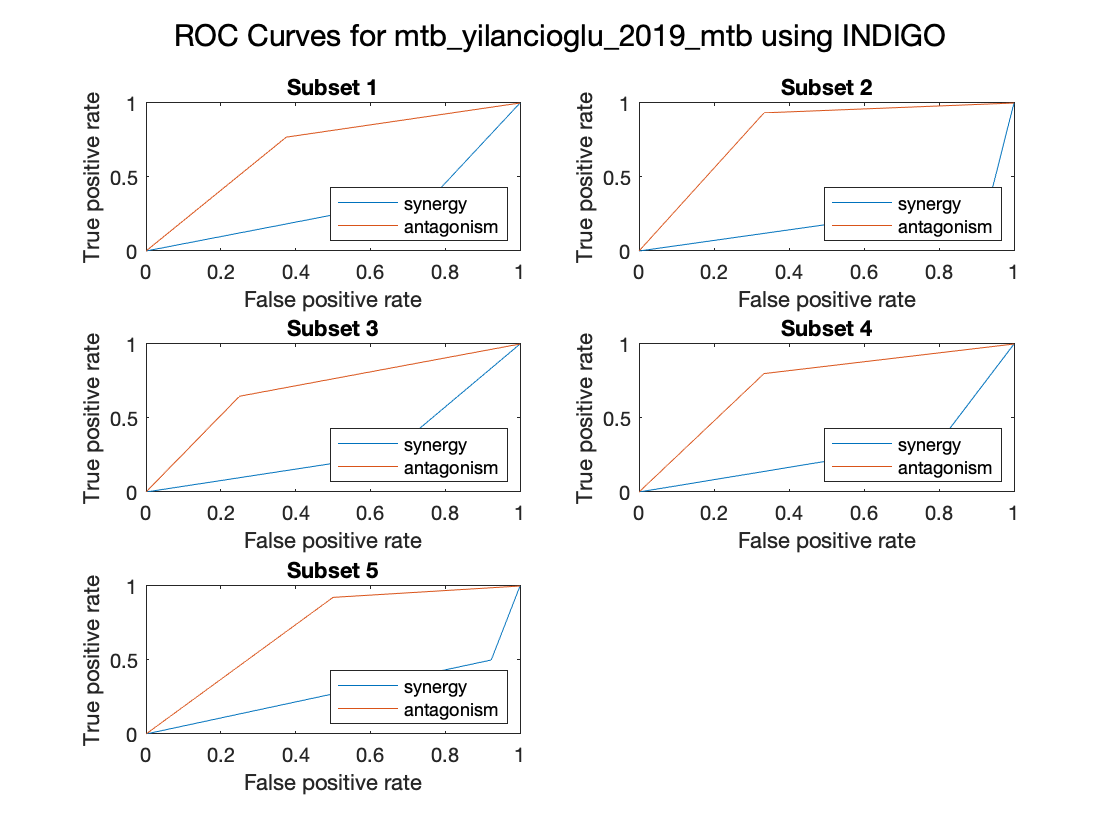

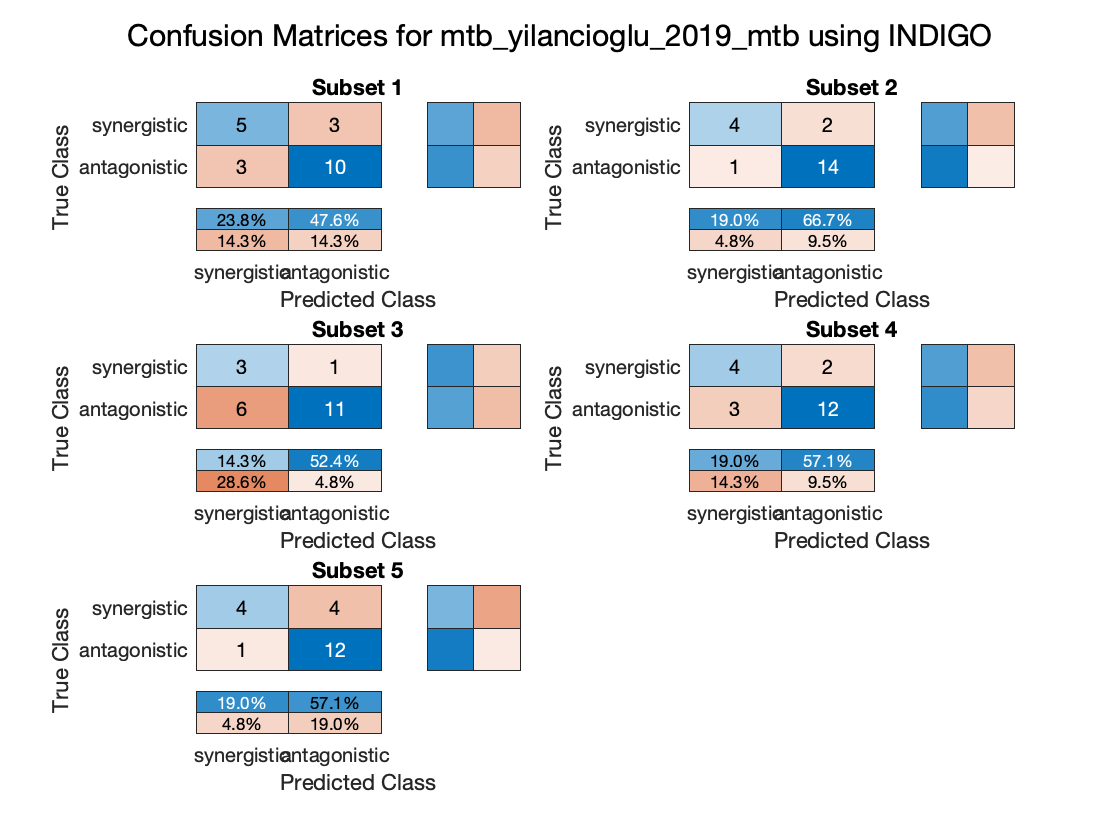

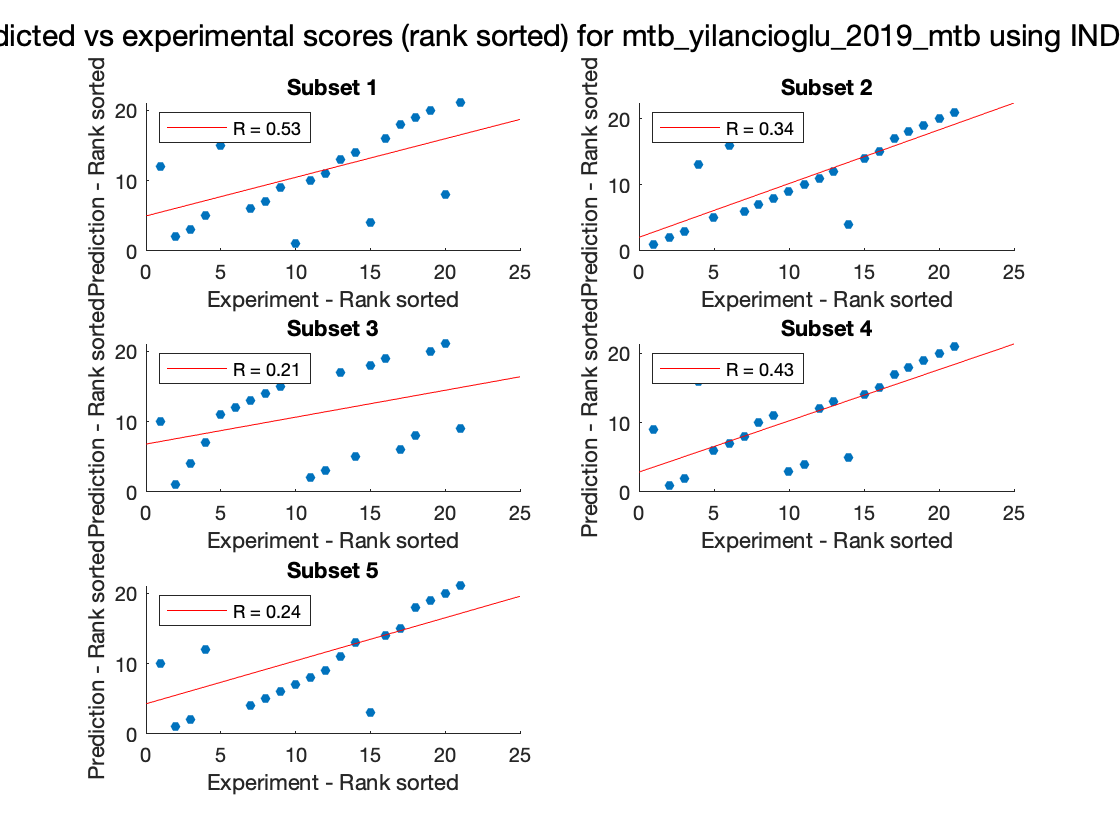

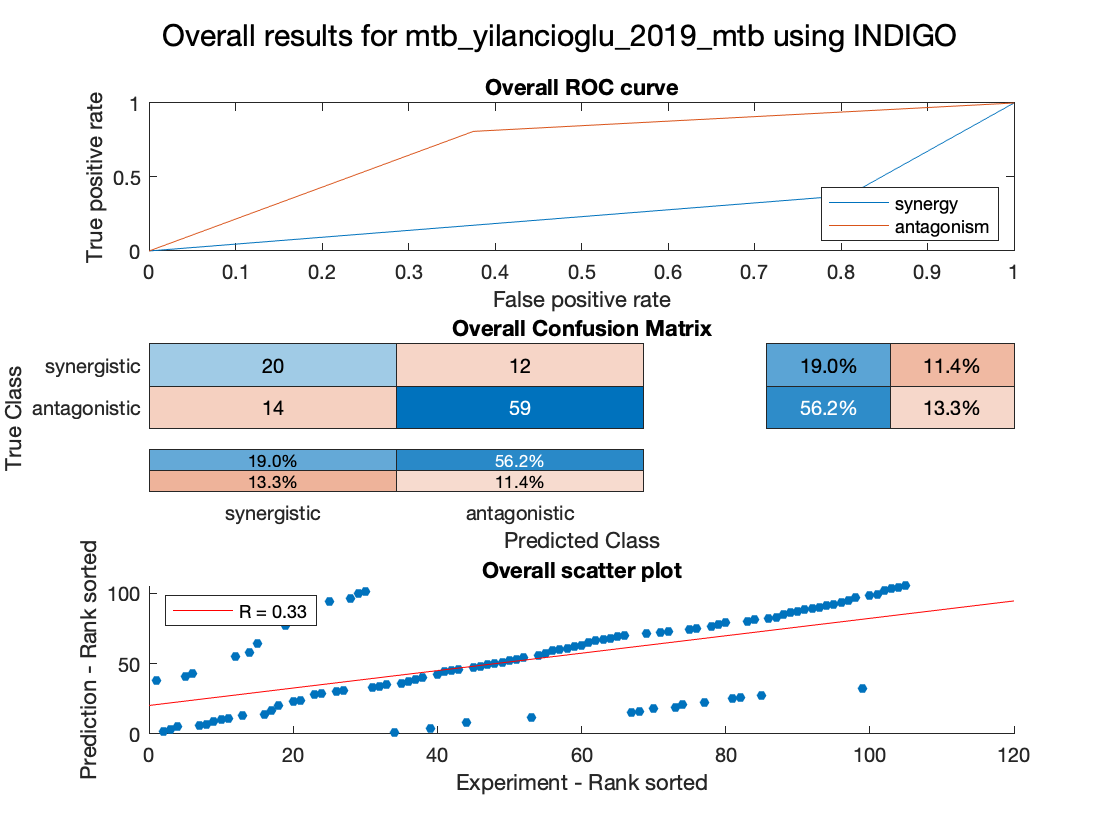

resultsTable = 5×11 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         21         0.52987     0.014741    0.71429        0.57143                0.625                0.625              

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                   21
    R (rank)                  0.34961
    P value                   0.17246
    Accuracy                  0.75238
    Absolute error            0.49524
    Precision (synergy)       0.62595
    Recall (synergy)          0.64167
    Precision (antagonism)    0.83361
    Recall (antagonism)       0.81454
    AUC - ROC (synergy)        0.2719
    AUC - ROC (antagonism)     0.7281


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     105
    R (rank)                      0.3313
    P value                   0.00055593
    Accuracy                     0.75238
    Absolute error               0.49524
    Precision (synergy)          0.58824
    Recall (synergy)               0.625
    Precision (antagonism)       0.83099
    Recall (antagonism)          0.80822
    AUC - ROC (synergy)          0.28339
    AUC - ROC (antagonism)       0.71661


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

valMethod = 'cv';
K = 5;
standardize = 'standardized';
modelType = 2;
input_type = 2;

%testdata = mtb_h37rv_chandrasekaran_2016.xlsx
testData = dataFiles{4};
trainingData = dataFiles([1:4-1 4+1:end]);
indigoSummary = indigoRun(testData,trainingData,valMethod,K,standardize,modelType,input_type);

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to trai

Results for mtb_yilancioglu_2019_mtb

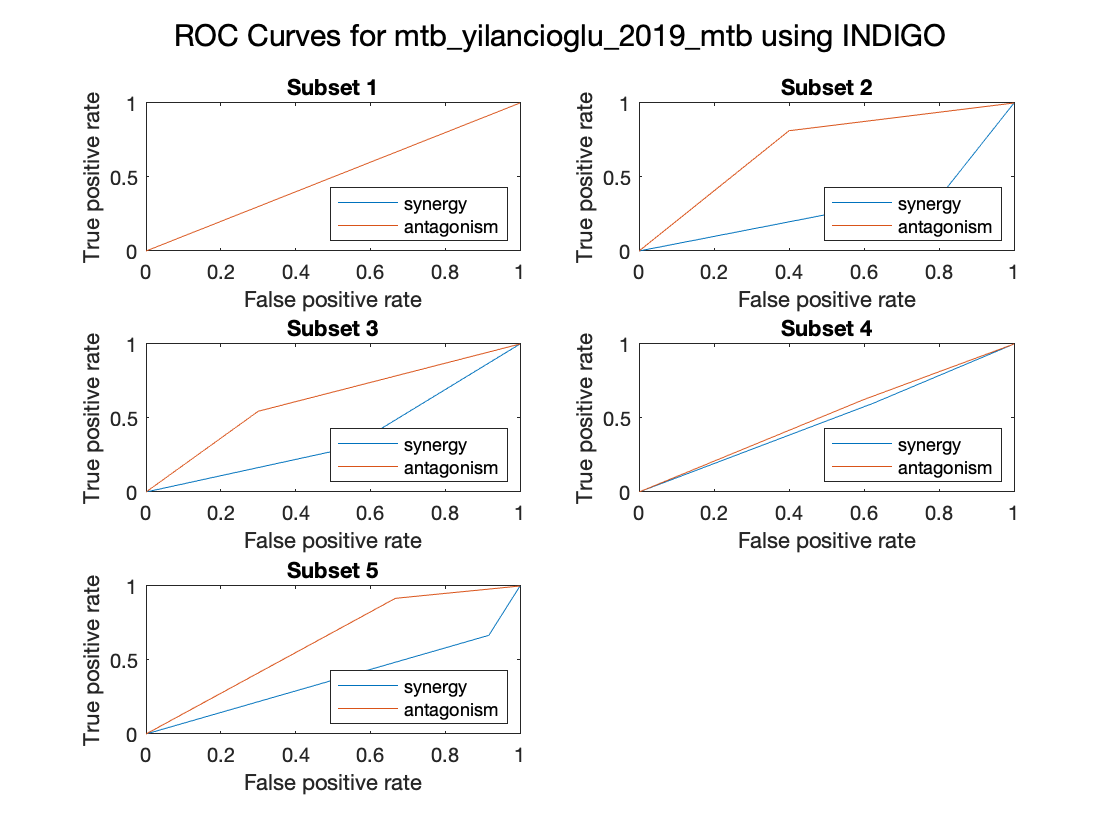

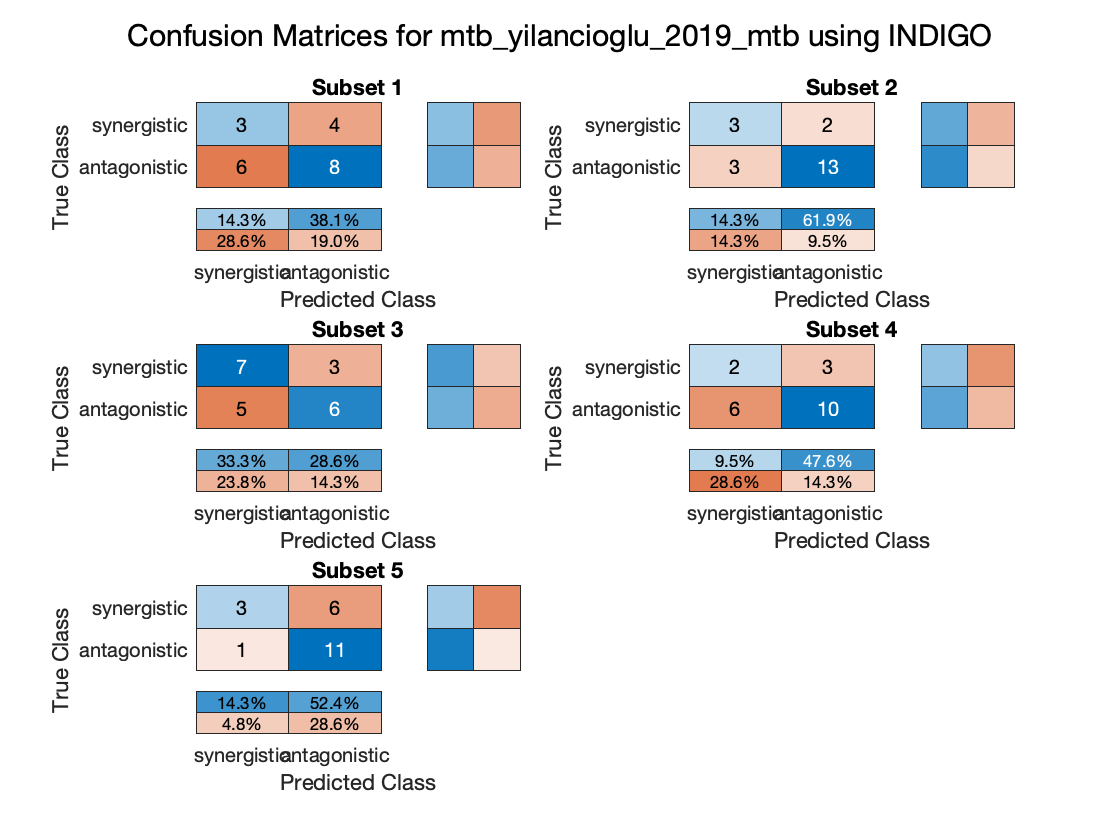

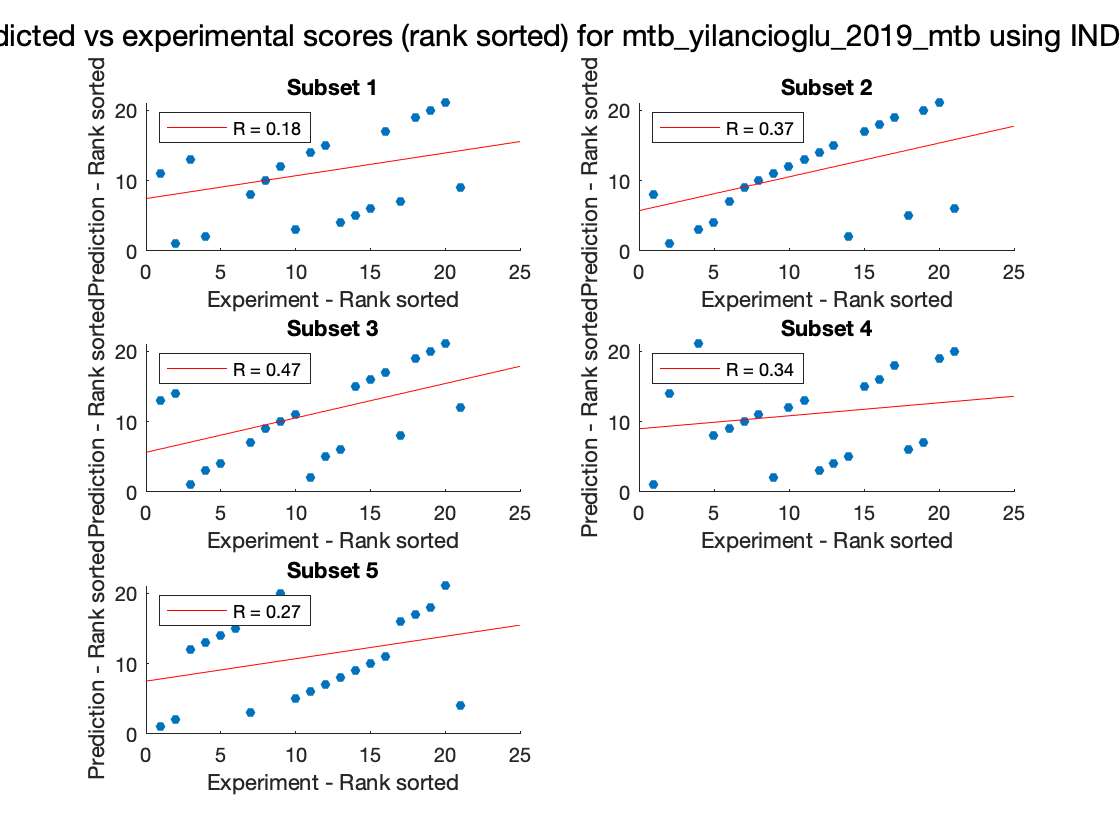

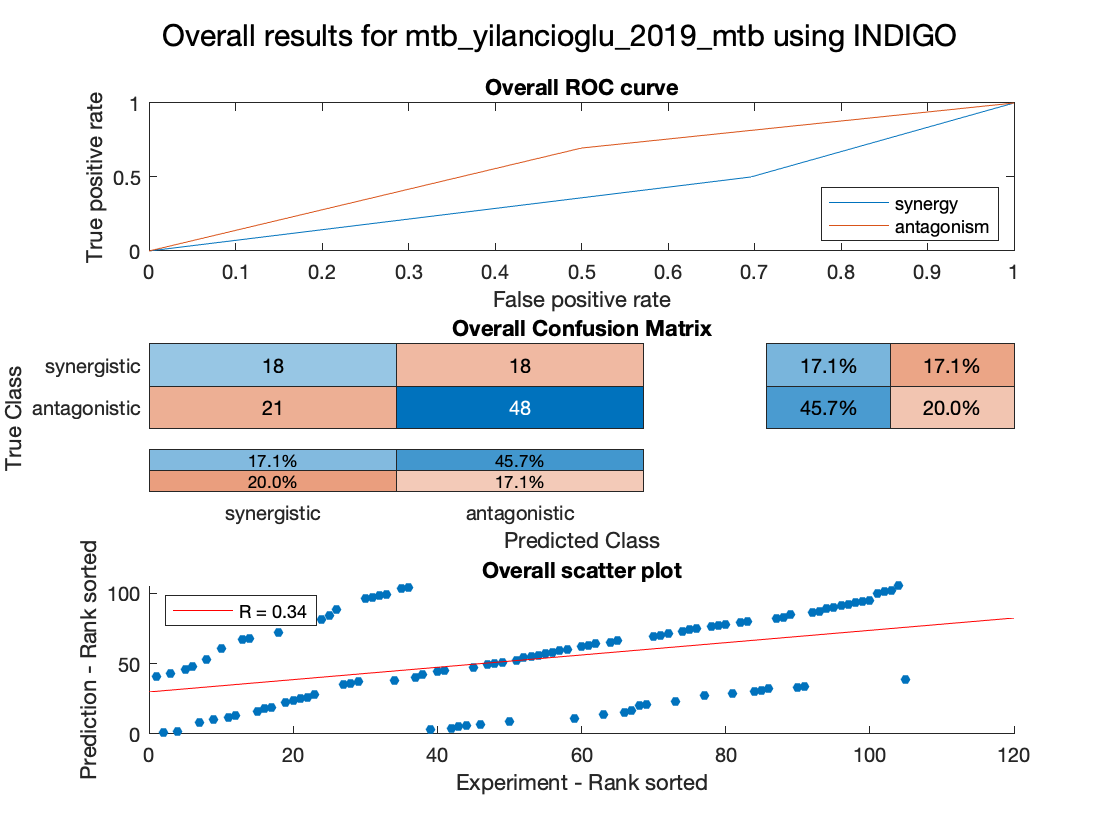

resultsTable = 5×11 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         21         0.18442      0.42182    0.52381        0.95238              0.33333              0.42857              

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                   21
    R (rank)                   0.3239
    P value                   0.18783
    Accuracy                  0.62857
    Absolute error            0.74286
    Precision (synergy)       0.48333
    Recall (synergy)          0.49238
    Precision (antagonism)    0.72326
    Recall (antagonism)       0.69421
    AUC - ROC (synergy)        0.4067
    AUC - ROC (antagonism)     0.5933


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     105
    R (rank)                     0.33801
    P value                   0.00042104
    Accuracy                     0.62857
    Absolute error               0.74286
    Precision (synergy)          0.46154
    Recall (synergy)                 0.5
    Precision (antagonism)       0.72727
    Recall (antagonism)          0.69565
    AUC - ROC (synergy)          0.40217
    AUC - ROC (antagonism)       0.59783


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

%testdata = mtb_yilancioglu_2019_mtb.xlsx
testData = dataFiles{18};
trainingData = dataFiles([1:18-1 18+1:end]);
indigoSummary = indigoRun(testData,trainingData,valMethod,K,standardize,modelType,input_type);
[stats,averages,overview] = analyze(indigoSummary);
save(saveIndigo(indigoSummary))

valMethod = 'independent';
K = 1;
standardize = '';

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to trai

Results for mtb_yilancioglu_2019_mtb

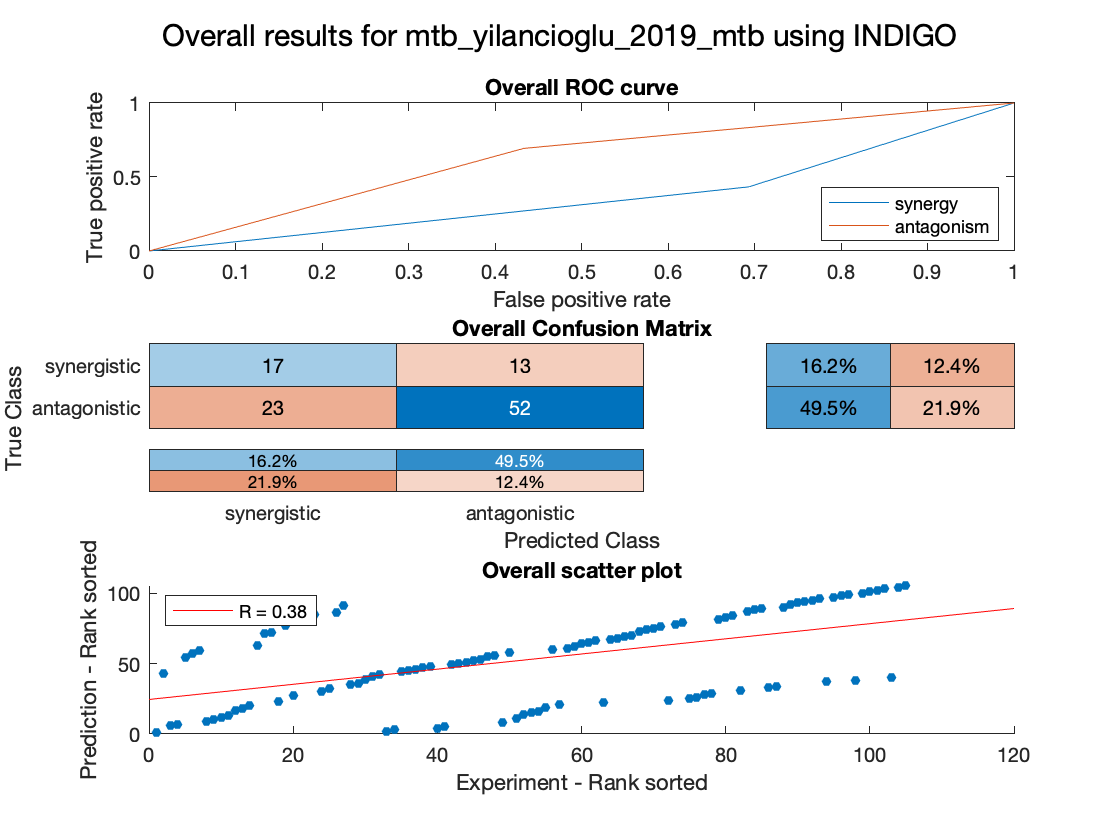

overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     105
    R (rank)                     0.38417
    P value                   5.9419e-05
    Accuracy                     0.65714
    Absolute error               0.68571
    Precision (synergy)            0.425
    Recall (synergy)             0.56667
    Precision (antagonism)           0.8
    Recall (antagonism)          0.69333
    AUC - ROC (synergy)             0.37
    AUC - ROC (antagonism)          0.63


modelType = 2;
input_type = 2;

%testdata = mtb_h37rv_chandrasekaran_2016.xlsx
testData = dataFiles{18};
trainingData = dataFiles([1:18-1 18+1:end]);
indigoSummary = indigoRun(testData,trainingData,valMethod,K,standardize,modelType,input_type);

[stats,averages,overview] = analyze(indigoSummary);
save(saveIndigo(indigoSummary))